## Задание 1. Слежение и компенсация: матричные уравнения.

A = [3 5 4 ;-2 -4 -5 ;2 2 3];
B = [2 ;-1 ;1];
Bf = [-2 2 ;-2 0 ;0 0];
C = [-2 -1 0];
D = 1;
Df = [4 1];
x0 = [0;0;0];
Gamma_f = [        35  56  22  -42 ;
        -11  -17  -7  12 ;
        -6  -10  -5  10 ;
        11  18  6  -13];
Yf = [        1  3 ;
        2  4 ;
        1  2 ;
        -1  -3]';
wf0 = [1;1;1;1];
Gamma_g = [        0   5   0  ;
        -5  0   0  ;
        0   0   0];
Yg = [8   0   2];
wg0 = [1; 0 ; 1];

eig(Gamma_f)

ans =    0.0000 + 3.0000i
   0.0000 - 3.0000i
  -0.0000 + 1.0000i
  -0.0000 - 1.0000i


eig(Gamma_g)

ans =    0.0000 + 5.0000i
   0.0000 - 5.0000i
   0.0000 + 0.0000i


function K = get_K(A, B)
    [~,notK,~] = icare(A, B, eye(3), 1, [], [], []);
    K=-notK;
end
function check_Gamma(A, B, C, D, K, Gamma)
    lambdas=eig(Gamma);
    for i=1:size(lambdas)
        rank([A+B*K-eye(size(A)).*lambdas(i), B; C+D*K, D])
    end
end
function Kg = get_Kg(A, B, C, D, K, Gamma_g, Yg)
    cvx_begin sdp
        variable Pg(3, 3)
        variable Kg(1, 3)
        Pg*Gamma_g-(A+B*K)*Pg==B*Kg;
        (C+D*K)*Pg+D*Kg==Yg;
    cvx_end
end
function Kf = get_Kf(A, B, C, D, K, Gamma_f, Bf, Yf, Df)
    cvx_begin sdp
        variable Pf(3, 4)
        variable Kf(1, 4)
        Pf*Gamma_f-(A+B*K)*Pf-Bf*Yf==B*Kf;
        (C+D*K)*Pf+D*Kf==-Df*Yf;
    cvx_end
end

K = get_K(A, B);
Kf = get_Kf(A, B, C, D, K, Gamma_f, Bf, Yf, Df);

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.5e-01|2.9e+03|5.3e+05| 0.000000e+00  0.000000e+00| 0:0:00| chol  2  2 
 1|1.000|0.857|3.7e-02|4.1e+02|1.9e+04| 0.000000e+00  8.841195e+03| 0:0:01| chol  1  2 
 2|1.000|0.593|3.9e-05|1.7e+02|1.2e+04| 0.000000e+00 -2.055276e+03| 0:0:01| chol  2  2 
 3|1.000|0.985|2.4e-06|2.5e+00|1.5e+02| 0.000000e+00 -2.928453e+01| 0:0:01| chol  2  1 
 4|1.000|0.98

Kg = get_Kg(A, B, C, D, K, Gamma_g, Yg);

 
Calling SDPT3 4.0: 12 variables, 12 equality constraints
------------------------------------------------------------

 num. of constraints = 12
 dim. of linear var  =  1
 dim. of free   var  = 12 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.9e-01|4.2e+02|5.0e+04| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.980|2.1e-08|8.6e+00|2.3e+02| 0.000000e+00  5.047807e-02| 0:0:00| chol  1  1 
 2|1.000|0.990|6.2e-08|9.9e-02|8.2e-01| 0.000000e+00  8.535065e-03| 0:0:00| chol  1  1 
 3|1.000|0.991|2.7e-08|1.8e-03|8.1e-03| 0.000000e+00  1.984827e-03| 0:0:00| chol  1  1 
 4|1.000|0.99

check_Gamma(A, B, C, D, K, Gamma_g);

ans = 4

ans = 4

ans = 4

check_Gamma(A, B, C, D, K, Gamma_f);

ans = 4

ans = 4

ans = 4

ans = 4

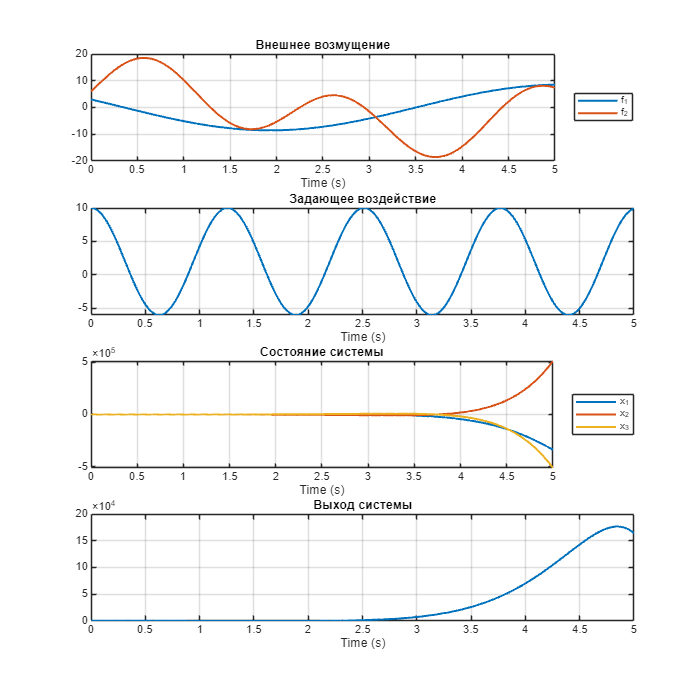

model_name = 'task1';
load_system(model_name);

K = zeros(1, 3);
Kf = zeros(1, 4);
Kg = zeros(1, 3);

sim_out = sim(model_name, 'StopTime', num2str(5));
t = sim_out.tout;
f = squeeze(sim_out.yout{4}.Values.Data);
g = squeeze(sim_out.yout{3}.Values.Data);
y = squeeze(sim_out.yout{2}.Values.Data);
x = squeeze(sim_out.yout{1}.Values.Data);

figure('Position', [0 0 700 700]);
m = 4; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(t, f, 'LineWidth', 1.5); hold on;
title('Внешнее возмущение');
xlabel('Time (s)');
legend({'f_1', 'f_2'}, 'Location', 'eastoutside');
grid on;

subplot(m, n, 2);
plot(t, g, 'LineWidth', 1.5); hold on;
title('Задающее воздействие');
xlabel('Time (s)');
grid on;

subplot(m, n, 3);
plot(t, x, 'LineWidth', 1.5); hold on;
title('Состояние системы');
xlabel('Time (s)');
legend({'x_1', 'x_2', 'x_3'}, 'Location', 'eastoutside');
grid on;

subplot(m, n, 4);
plot(t, y, 'LineWidth', 1.5); hold on;
title('Выход системы');
xlabel('Time (s)');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/10_sim.png'], 'Resolution', 500);

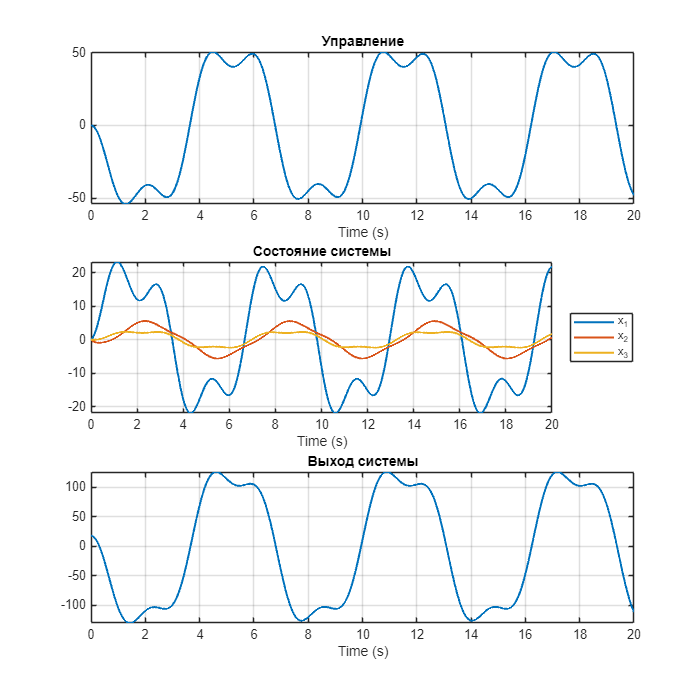

model_name = 'task1';
load_system(model_name);

K = get_K(A, B);
Kf = zeros(1, 4);
Kg = zeros(1, 3);

sim_out = sim(model_name, 'StopTime', num2str(20));
t = sim_out.tout;
u = squeeze(sim_out.yout{5}.Values.Data);
y = squeeze(sim_out.yout{2}.Values.Data);
x = squeeze(sim_out.yout{1}.Values.Data);

figure('Position', [0 0 700 700]);
m = 3; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(t, u, 'LineWidth', 1.5); hold on;
title('Управление');
xlabel('Time (s)');
grid on;

subplot(m, n, 2);
plot(t, x, 'LineWidth', 1.5); hold on;
title('Состояние системы');
xlabel('Time (s)');
legend({'x_1', 'x_2', 'x_3'}, 'Location', 'eastoutside');
grid on;

subplot(m, n, 3);
plot(t, y, 'LineWidth', 1.5); hold on;
title('Выход системы');
xlabel('Time (s)');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/11_sim.png'], 'Resolution', 500);

model_name = 'task1';
load_system(model_name);

K = get_K(A, B);
Kf = get_Kf(A, B, C, D, K, Gamma_f, Bf, Yf, Df);

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.5e-01|2.9e+03|5.3e+05| 0.000000e+00  0.000000e+00| 0:0:00| chol  2  2 
 1|1.000|0.857|3.7e-02|4.1e+02|1.9e+04| 0.000000e+00  8.841195e+03| 0:0:01| chol  1  2 
 2|1.000|0.593|3.9e-05|1.7e+02|1.2e+04| 0.000000e+00 -2.055276e+03| 0:0:01| chol  2  2 
 3|1.000|0.985|2.4e-06|2.5e+00|1.5e+02| 0.000000e+00 -2.928453e+01| 0:0:01| chol  2  1 
 4|1.000|0.98

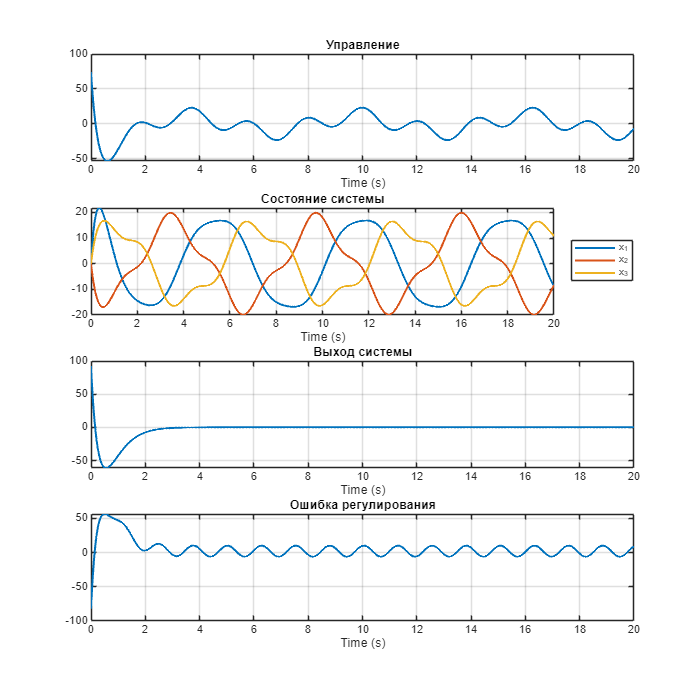

Kg = zeros(1, 3);

sim_out = sim(model_name, 'StopTime', num2str(20));
t = sim_out.tout;
u = squeeze(sim_out.yout{5}.Values.Data);
y = squeeze(sim_out.yout{2}.Values.Data);
x = squeeze(sim_out.yout{1}.Values.Data);
g = squeeze(sim_out.yout{3}.Values.Data);

e = g - y;

figure('Position', [0 0 700 700]);
m = 4; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(t, u, 'LineWidth', 1.5); hold on;
title('Управление');
xlabel('Time (s)');
grid on;

subplot(m, n, 2);
plot(t, x, 'LineWidth', 1.5); hold on;
title('Состояние системы');
xlabel('Time (s)');
legend({'x_1', 'x_2', 'x_3'}, 'Location', 'eastoutside');
grid on;

subplot(m, n, 3);
plot(t, y, 'LineWidth', 1.5); hold on;
title('Выход системы');
xlabel('Time (s)');
grid on;

subplot(m, n, 4);
plot(t, e, 'LineWidth', 1.5); hold on;
title('Ошибка регулирования');
xlabel('Time (s)');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/12_sim.png'], 'Resolution', 500);

model_name = 'task1';
load_system(model_name);

K = get_K(A, B);
Kf = zeros(1, 4);
Kg = get_Kg(A, B, C, D, K, Gamma_g, Yg);

 
Calling SDPT3 4.0: 12 variables, 12 equality constraints
------------------------------------------------------------

 num. of constraints = 12
 dim. of linear var  =  1
 dim. of free   var  = 12 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.9e-01|4.2e+02|5.0e+04| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.980|2.1e-08|8.6e+00|2.3e+02| 0.000000e+00  5.047807e-02| 0:0:00| chol  1  1 
 2|1.000|0.990|6.2e-08|9.9e-02|8.2e-01| 0.000000e+00  8.535065e-03| 0:0:00| chol  1  1 
 3|1.000|0.991|2.7e-08|1.8e-03|8.1e-03| 0.000000e+00  1.984827e-03| 0:0:00| chol  1  1 
 4|1.000|0.99

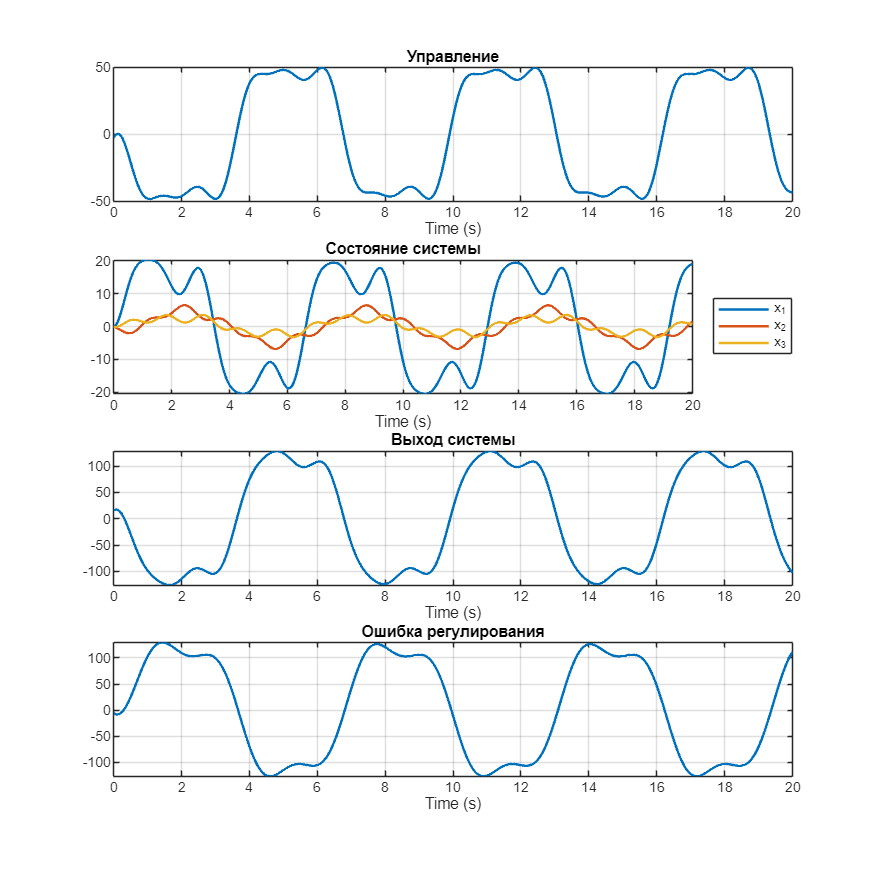


sim_out = sim(model_name, 'StopTime', num2str(20));
t = sim_out.tout;
u = squeeze(sim_out.yout{5}.Values.Data);
y = squeeze(sim_out.yout{2}.Values.Data);
x = squeeze(sim_out.yout{1}.Values.Data);
g = squeeze(sim_out.yout{3}.Values.Data);

e = g - y;

figure('Position', [0 0 700 700]);
m = 4; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(t, u, 'LineWidth', 1.5); hold on;
title('Управление');
xlabel('Time (s)');
grid on;

subplot(m, n, 2);
plot(t, x, 'LineWidth', 1.5); hold on;
title('Состояние системы');
xlabel('Time (s)');
legend({'x_1', 'x_2', 'x_3'}, 'Location', 'eastoutside');
grid on;

subplot(m, n, 3);
plot(t, y, 'LineWidth', 1.5); hold on;
title('Выход системы');
xlabel('Time (s)');
grid on;

subplot(m, n, 4);
plot(t, e, 'LineWidth', 1.5); hold on;
title('Ошибка регулирования');
xlabel('Time (s)');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/13_sim.png'], 'Resolution', 500);

model_name = 'task1';
load_system(model_name);

K = get_K(A, B);
Kf = get_Kf(A, B, C, D, K, Gamma_f, Bf, Yf, Df);

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.5e-01|2.9e+03|5.3e+05| 0.000000e+00  0.000000e+00| 0:0:00| chol  2  2 
 1|1.000|0.857|3.7e-02|4.1e+02|1.9e+04| 0.000000e+00  8.841195e+03| 0:0:00| chol  1  2 
 2|1.000|0.593|3.9e-05|1.7e+02|1.2e+04| 0.000000e+00 -2.055276e+03| 0:0:00| chol  2  2 
 3|1.000|0.985|2.4e-06|2.5e+00|1.5e+02| 0.000000e+00 -2.928453e+01| 0:0:00| chol  2  1 
 4|1.000|0.98

Kg = get_Kg(A, B, C, D, K, Gamma_g, Yg);

 
Calling SDPT3 4.0: 12 variables, 12 equality constraints
------------------------------------------------------------

 num. of constraints = 12
 dim. of linear var  =  1
 dim. of free   var  = 12 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.9e-01|4.2e+02|5.0e+04| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.980|2.1e-08|8.6e+00|2.3e+02| 0.000000e+00  5.047807e-02| 0:0:00| chol  1  1 
 2|1.000|0.990|6.2e-08|9.9e-02|8.2e-01| 0.000000e+00  8.535065e-03| 0:0:00| chol  1  1 
 3|1.000|0.991|2.7e-08|1.8e-03|8.1e-03| 0.000000e+00  1.984827e-03| 0:0:00| chol  1  1 
 4|1.000|0.99

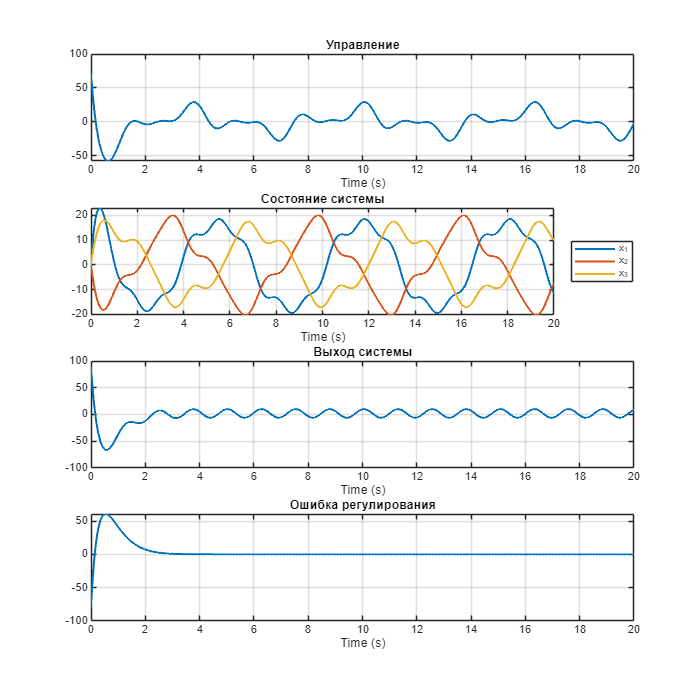


sim_out = sim(model_name, 'StopTime', num2str(20));
t = sim_out.tout;
u = squeeze(sim_out.yout{5}.Values.Data);
y = squeeze(sim_out.yout{2}.Values.Data);
x = squeeze(sim_out.yout{1}.Values.Data);
g = squeeze(sim_out.yout{3}.Values.Data);

e = g - y;

figure('Position', [0 0 700 700]);
m = 4; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(t, u, 'LineWidth', 1.5); hold on;
title('Управление');
xlabel('Time (s)');
grid on;

subplot(m, n, 2);
plot(t, x, 'LineWidth', 1.5); hold on;
title('Состояние системы');
xlabel('Time (s)');
legend({'x_1', 'x_2', 'x_3'}, 'Location', 'eastoutside');
grid on;

subplot(m, n, 3);
plot(t, y, 'LineWidth', 1.5); hold on;
title('Выход системы');
xlabel('Time (s)');
grid on;

subplot(m, n, 4);
plot(t, e, 'LineWidth', 1.5); hold on;
title('Ошибка регулирования');
xlabel('Time (s)');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/14_sim.png'], 'Resolution', 500);

## Задание 2. Слежение и компенсация по выходу.

function observable(C, A)
    Ob = obsv(A, C)
    rank_Ob = rank(Ob)
    if rank_Ob == size(A, 1)
        fprintf('YES\n');
    else
        fprintf('NO\n');
    end
end
function controllable(A, B)
    Co = ctrb(A, B)
    rank_Co = rank(Co)
    if rank_Co == size(A, 1)
        fprintf('YES\n');
    else
        fprintf('NO\n');
    end
end
function Q = get_Q(Gamma_g, Gamma, Y, Yg)
    cvx_begin sdp
        variable Q(size(Gamma, 2), size(Gamma_g, 1))
        Q*Gamma_g-Gamma*Q==Y*Yg;
    cvx_end
end

Gamma = diag([-2, -3, -4]);
Y = [1; 1; 1];
controllable(Gamma_g, Y)

Co =      1     5   -25
     1    -5   -25
     1     0     0


rank_Co = 3

YES


observable(Yg, Gamma)

Ob =      8     0     2
   -16     0    -8
    32     0    32


rank_Ob = 2

NO


obsQ = get_Q(Gamma_g, Gamma, Y, Yg)

Unrecognized function or variable 'Gamma'.

Abar = [Gamma_f zeros(4, 3); Bf*Yf A]

Abar =     35    56    22   -42     0     0     0
   -11   -17    -7    12     0     0     0
    -6   -10    -5    10     0     0     0
    11    18     6   -13     0     0     0
     4     4     2    -4     3     5     4
    -2    -4    -2     2    -2    -4    -5
     0     0     0     0     2     2     3


Bbar = [zeros(4, 1);B]

Bbar =      0
     0
     0
     0
     2
    -1
     1


Cbar = [Df*Yf C]

Cbar =      7    12     6    -7    -2    -1     0


eig(Abar)

ans =   -0.0000 + 3.0000i
  -0.0000 - 3.0000i
  -2.0000 + 0.0000i
   2.0000 + 1.0000i
   2.0000 - 1.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i


G1 = diag([-1 -3 -4 -5 -6 -7 -8]);
Y1 = ones(7, 1);
controllable(Abar, Y1)

Co =            1          71          31        -551        -319        4871        2911
           1         -23         -49         119         481        -983       -4369
           1         -11          79          59        -799        -491        7279
           1          22          15        -262        -159        2422        1455
           1          18          79         420         115        -350        1219
           1         -17          13        -319        -845       -1661         245
           1           7          23         253         961        1423         247


rank_Co = 7

YES


observable(Cbar, G1)

Ob =            7          12           6          -7          -2          -1           0
          -7         -36         -24          35          12           7           0
           7         108          96        -175         -72         -49           0
          -7        -324        -384         875         432         343           0
           7         972        1536       -4375       -2592       -2401           0
          -7       -2916       -6144       21875       15552       16807           0
           7        8748       24576     -109375      -93312     -117649           0


rank_Ob = 6

NO


cvx_begin sdp quiet;
    variable Q1(7,7);
    G1*Q1-Q1*Abar == Y1*Cbar;
cvx_end;
L = inv(Q1) * Y1;
eig(Abar+L*Cbar)

ans =    -8.0000
   -7.0000
   -6.0000
   -5.0000
   -4.0000
   -3.0000
   -1.0000


K = [-1.5798 -1.3778 -7.1171];
Kg = [0.2677 -1.1433 0.5000];
Kf = [38.5358 57.3857 26.7383 -48.4226];
xf0 = [wf0; x0];
wg_bar0 = [0;0;0];

G = diag([-2, -3, -4]);
Y = [1; 1; 1];
observable(Yg, Gamma_g)

Ob =      8     0     2
     0    40     0
  -200     0     0


rank_Ob = 3

YES


cvx_begin sdp quiet;
    variable Q(3,3);
    Q*Gamma_g - G * Q == Y * Yg;
cvx_end;
Q

Q =     0.5517   -1.3793    1.0000
    0.7059   -1.1765    0.6667
    0.7805   -0.9756    0.5000


tspan = 0:0.01:6;

z0 = [wf0; x0; wg0; zeros(10,1)];  % 23x1: wf(4), x(3), wg(3), hat_wf(4), hat_x(3), tilde_wg(3)

%% Функция управления
u = @(t, z) K * z(15:17) + Kg * inv(Q) * z(18:20) + Kf * z(11:14);

%% Функция динамики
ode_obs = @(t, z) [
    [Abar * z(1:7) + Bbar * u(t, z); ... % Истинная система
     Gamma_g * z(8:10); ... % Динамика задания
     Abar * z(11:17) + (Bbar + L*D) * u(t, z) ...
     + L * (Cbar * z(11:17) - Cbar * z(1:7) - D * u(t, z))]; ... % Наблюдатель расширенный
    Gamma * z(18:20) + Y * (Yg * z(8:10))
];

%% Решение
[t, z] = ode45(ode_obs, tspan, z0);

x = z(:,5:7)';
wg_hat = inv(Q) * z(:,18:20)';
wf_hat = z(:,11:14)';
x_hat = z(:,15:17)';
wf = z(:, 1:4)';
wg = z(:, 8:10)';
u = K * x_hat + Kg * wg_hat + Kf * wf_hat;
y = C * x + D * u + Df * (Yf * wf);
g = 3 * cos(4 * t') - 4;
e = g - y;

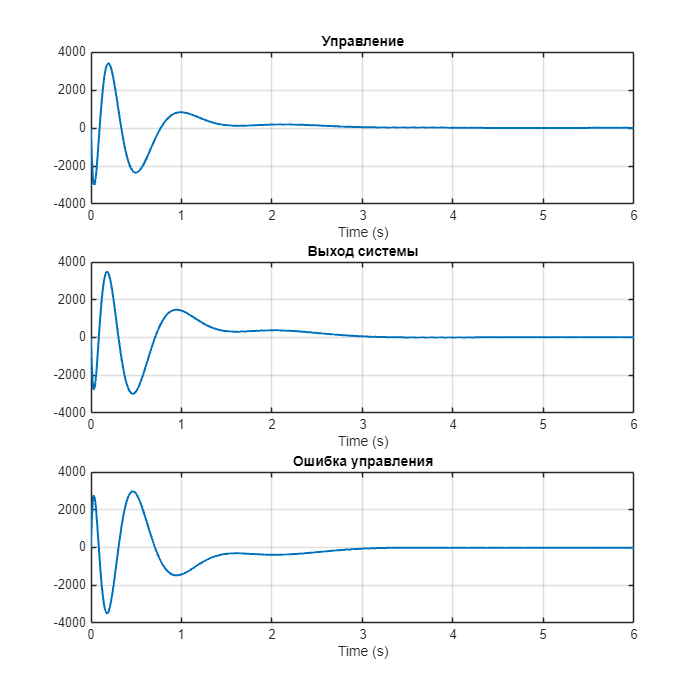

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure('Position', [0 0 700 700]);
m = 3; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(tspan, u, 'LineWidth', 1.5); hold on;
title('Управление');
xlabel('Time (s)');
grid on;

subplot(m, n, 2);
plot(tspan,y, 'LineWidth', 1.5); hold on;
title('Выход системы');
xlabel('Time (s)');
grid on;

subplot(m, n, 3);
plot(tspan, e, 'LineWidth', 1.5); hold on;
title('Ошибка управления');
xlabel('Time (s)');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/20_sim.png'], 'Resolution', 500);

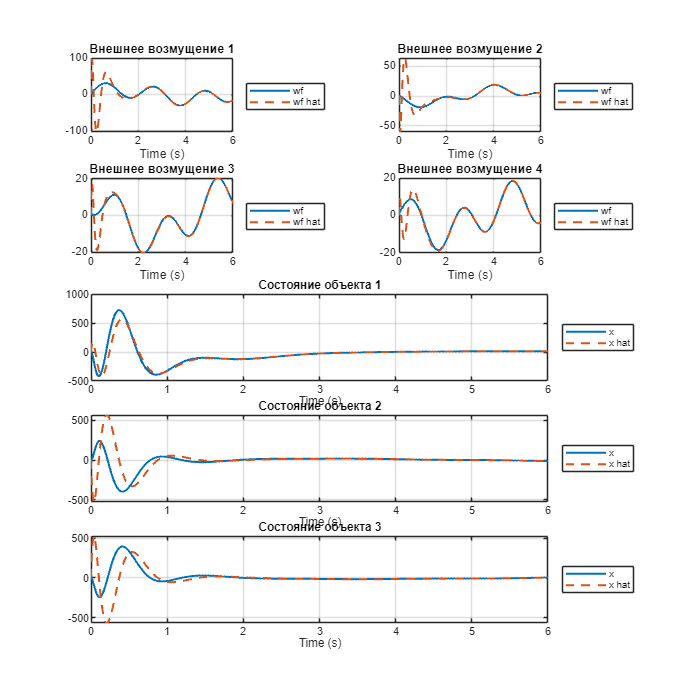

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
t = tspan;

figure('Position', [0 0 700 700]);
m = 5; % Number of rows
n = 2; % Number of columns

for i=1:4
    subplot(m, n, i);
    plot(t, wf(i, :), 'LineWidth', 1.5); hold on;
    plot(t, wf_hat(i, :), '--', 'LineWidth', 1.5);
    title(['Внешнее возмущение ' int2str(i)]);
    legend({'wf', 'wf hat'}, 'Location', 'eastoutside');
    xlabel('Time (s)');
    grid on;
end

for i=1:3
    subplot(m, n, [2*i+3, 2*i+4]);
    plot(t, x(i, :), 'LineWidth', 1.5); hold on;
    plot(t, x_hat(i, :), '--', 'LineWidth', 1.5);
    title(['Состояние объекта ' int2str(i)]);
    legend({'x', 'x hat'}, 'Location', 'eastoutside');
    xlabel('Time (s)');
    grid on;
end

% Save the figure
exportgraphics(gcf, ['figs/21_sim.png'], 'Resolution', 500);

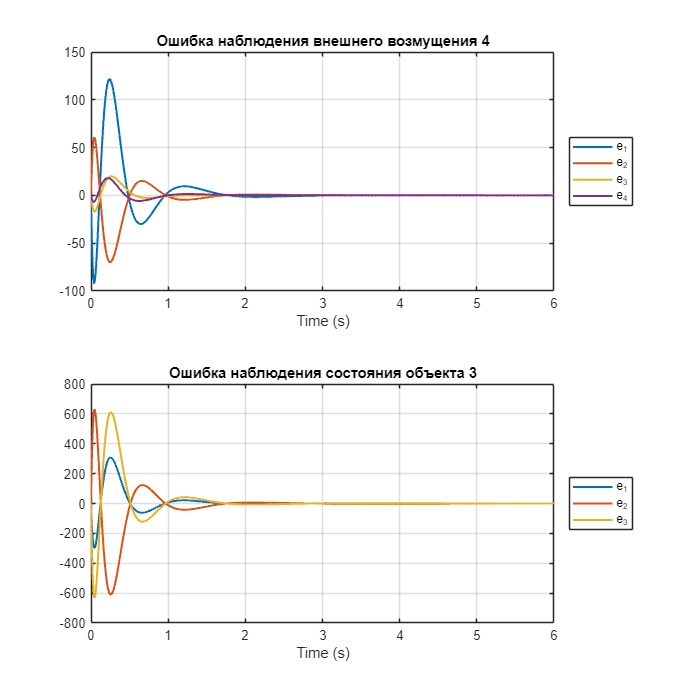

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure('Position', [0 0 700 700]);
m = 2; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
for i=1:4
    plot(t, wf(i, :) -  wf_hat(i, :), 'LineWidth', 1.5); hold on;
end
title(['Ошибка наблюдения внешнего возмущения ' int2str(i)]);
legend({'e_1', 'e_2', 'e_3', 'e_4'}, 'Location', 'eastoutside');
xlabel('Time (s)');
grid on;

subplot(m, n, 2);
for i=1:3
    plot(t, x(i, :) - x_hat(i, :), 'LineWidth', 1.5); hold on;
end
title(['Ошибка наблюдения состояния объекта ' int2str(i)]);
legend({'e_1', 'e_2', 'e_3'}, 'Location', 'eastoutside');
xlabel('Time (s)');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/22_sim.png'], 'Resolution', 500);

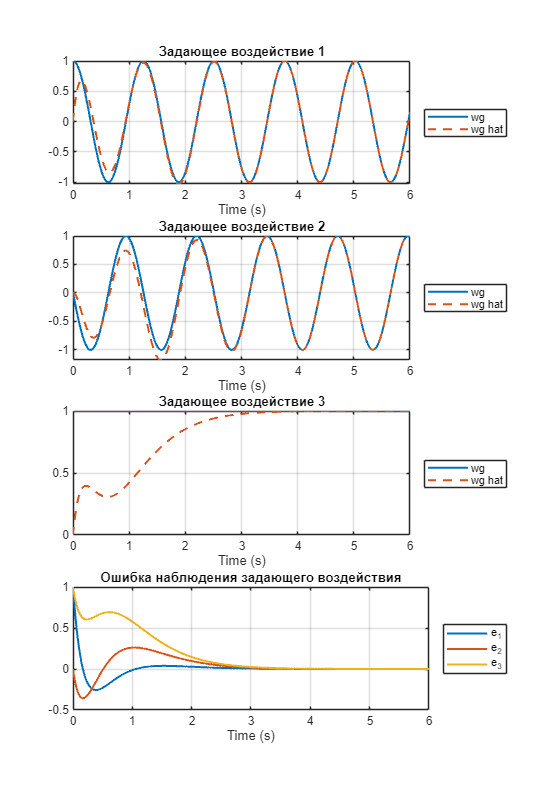

figure('Position', [0 0 700 1000]);
m = 4; % Number of rows
n = 1; % Number of columns

for i=1:3
    subplot(m, n, i);
    plot(t, wg(i, :), 'LineWidth', 1.5); hold on;
    plot(t, wg_hat(i, :), '--', 'LineWidth', 1.5);
    title(['Задающее воздействие ' int2str(i)]);
    legend({'wg', 'wg hat'}, 'Location', 'eastoutside');
    xlabel('Time (s)');
    grid on;
end

subplot(m, n, 4);
for i=1:3
    plot(t, wg(i, :)-wg_hat(i, :), 'LineWidth', 1.5); hold on;
end
title(['Ошибка наблюдения задающего воздействия']);
legend({'e_1', 'e_2', 'e_3'}, 'Location', 'eastoutside');
xlabel('Time (s)');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/23_sim.png'], 'Resolution', 500);

## Задание 3. Слежение и компенсация: наблюдатели возмущения.

Gamma = diag([-2, -3, -4]);
Y = [1; 1; 1];
cvx_begin sdp quiet;
    variable Q(3,3);
    Q*Gamma_g - Gamma * Q == Y * Yg;
cvx_end;
Q

Q =     0.5517   -1.3793    1.0000
    0.7059   -1.1765    0.6667
    0.7805   -0.9756    0.5000


cvx_begin sdp quiet;
    variable Cbar(2,3);
    Cbar*Bf == eye(2);
cvx_end;
Cbar

Cbar =          0   -0.5000         0
    0.5000   -0.5000         0


G1 = diag([-1 -2 -3 -4]);
Y1 = [1 1; 1 1; 1 1; 1 1]';
cvx_begin sdp quiet;
    variable Q1(4,4);
    Q1*G1-Gamma_f'*Q1 == Yf'*Y1;
cvx_end;
L = (-Y1*pinv(Q1))'

L =    11.2500   11.2500
    0.6250    0.6250
   -3.7500   -3.7500
    6.8750    6.8750


F = Gamma_f - L * Yf

F =   -10.0000  -11.5000  -11.7500    3.0000
  -13.5000  -20.7500   -8.8750   14.5000
    9.0000   12.5000    6.2500   -5.0000
  -16.5000  -23.2500  -14.6250   14.5000


z0_hat = zeros(4, 1);
wg0_bar = zeros(3, 1);
model_name = 'task31';
load_system(model_name);
out = sim(model_name, 'StopTime', num2str(10));

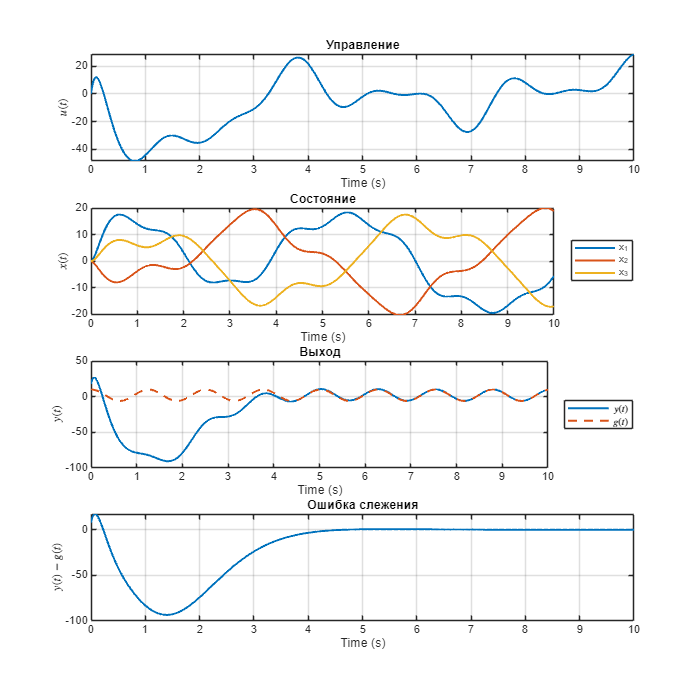

figure('Position', [0 0 700 700]);
m = 4; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(out.u, 'LineWidth', 1.5); hold on;
title('Управление');
xlabel('Time (s)');
ylabel('$u(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 2);
plot(out.x, 'LineWidth', 1.5); hold on;
title('Состояние');
xlabel('Time (s)');
legend({'x_1', 'x_2', 'x_3'}, 'Location', 'eastoutside');
ylabel('$x(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 3);
plot(out.y, 'LineWidth', 1.5); hold on;
plot(out.g, '--', 'LineWidth', 1.5);
legend({'$y(t)$', '$g(t)$'}, 'Location', 'eastoutside', 'Interpreter', 'latex');
title('Выход');
xlabel('Time (s)');
ylabel('$y(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 4);
plot(out.y-out.g, 'LineWidth', 1.5); hold on;
title('Ошибка слежения');
xlabel('Time (s)');
ylabel('$y(t)-g(t)$', 'Interpreter', 'latex');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/30_sim.png'], 'Resolution', 500);

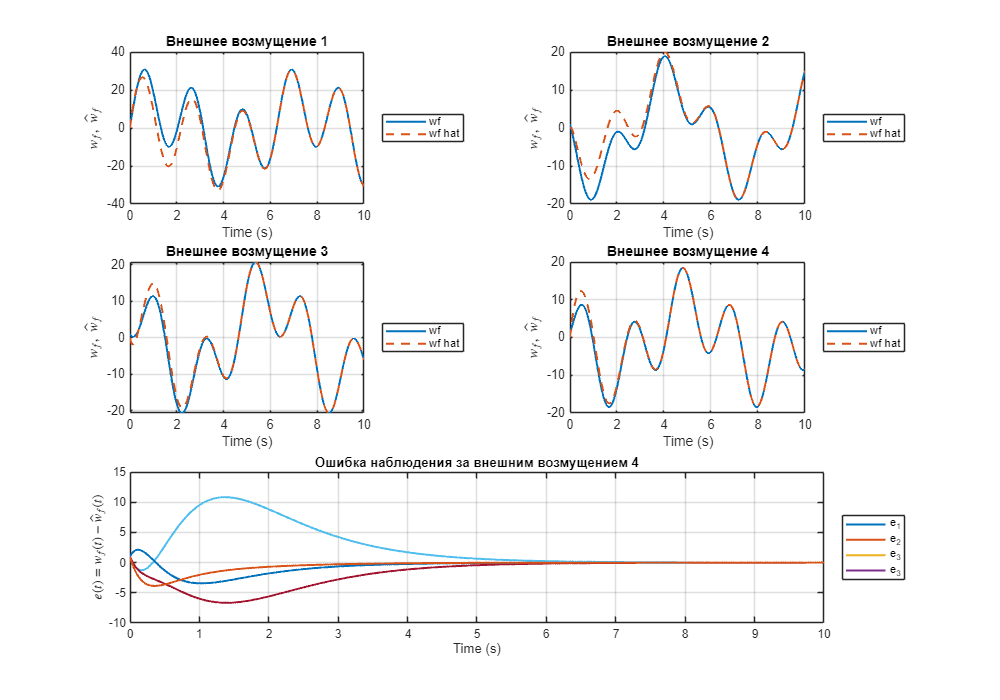

figure('Position', [0 0 1000 700]);
m = 3; % Number of rows
n = 2; % Number of columns

for i=1:4
    subplot(m, n, i);
    plot(out.wf.Time, out.wf.Data(:, i), 'LineWidth', 1.5); hold on;
    plot(out.wf_hat.Time, out.wf_hat.Data(:, i), '--', 'LineWidth', 1.5);
    title(['Внешнее возмущение ' int2str(i)]);
    legend({'$w_f$', '$\hat w_f$'}, 'Location', 'eastoutside', 'Interpreter', 'latex');
    xlabel('Time (s)');
    ylabel('$w_f,\ \hat w_f$', 'Interpreter', 'latex');
    grid on;
end

subplot(m, n, [5,6]);
for i=1:4
    plot(out.wf-out.wf_hat, 'LineWidth', 1.5); hold on;
end
title(['Ошибка наблюдения за внешним возмущением ' int2str(i)]);
legend({'e_1', 'e_2', 'e_3', 'e_3'}, 'Location', 'eastoutside');
xlabel('Time (s)');
ylabel('$e(t)=w_f(t)-\hat w_f(t)$', 'Interpreter', 'latex');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/31_sim.png'], 'Resolution', 500);

Gamma_ff = diag([-1 -2 -3 -4]);
Yff = ones(4,1);
observable(Df*Yf, Gamma_f);

Ob =      7    12     6    -7
     0     2    -2     1
     1     4     2    -9
  -120  -194   -70   143


rank_Ob = 4

YES


controllable(Gamma_ff, Yff)

Co =      1    -1     1    -1
     1    -2     4    -8
     1    -3     9   -27
     1    -4    16   -64


rank_Co = 4

YES


cvx_begin sdp quiet;
    variable Qff(4,4);
    Qff*Gamma_f-Gamma_ff'*Qff == Yff*Df*Yf;
cvx_end;
Qff

Qff =     9.9000   15.4000    8.0000  -12.0000
    4.8923    7.8462    4.1538   -5.7077
    2.9000    4.7333    2.5333   -3.2667
    2.0047    3.3082    1.7741   -2.1953


wf_bar = zeros(4,1);
model_name = 'task32';
load_system(model_name);
out = sim(model_name, 'StopTime', num2str(10));

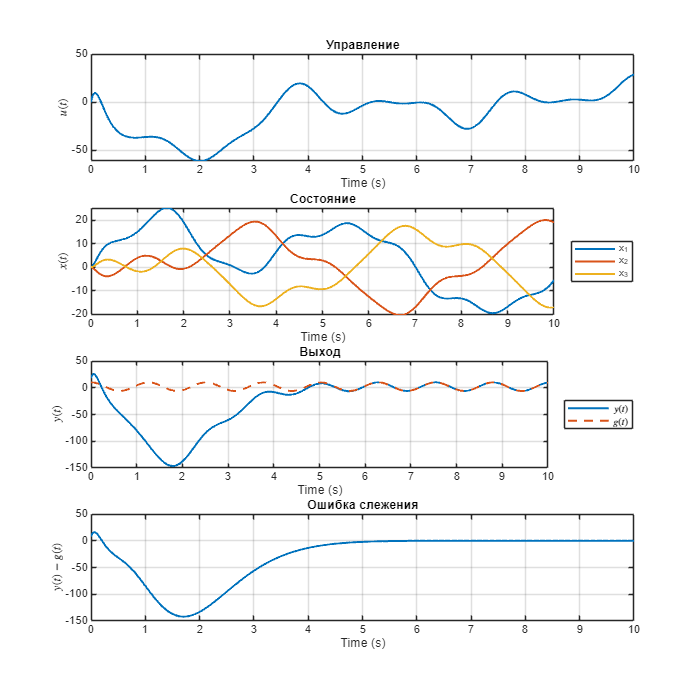

figure('Position', [0 0 700 700]);
m = 4; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(out.u, 'LineWidth', 1.5); hold on;
title('Управление');
xlabel('Time (s)');
ylabel('$u(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 2);
plot(out.x, 'LineWidth', 1.5); hold on;
title('Состояние');
xlabel('Time (s)');
legend({'x_1', 'x_2', 'x_3'}, 'Location', 'eastoutside');
ylabel('$x(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 3);
plot(out.y, 'LineWidth', 1.5); hold on;
plot(out.g, '--', 'LineWidth', 1.5);
legend({'$y(t)$', '$g(t)$'}, 'Location', 'eastoutside', 'Interpreter', 'latex');
title('Выход');
xlabel('Time (s)');
ylabel('$y(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 4);
plot(out.y-out.g, 'LineWidth', 1.5); hold on;
title('Ошибка слежения');
xlabel('Time (s)');
ylabel('$y(t)-g(t)$', 'Interpreter', 'latex');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/32_sim.png'], 'Resolution', 500);

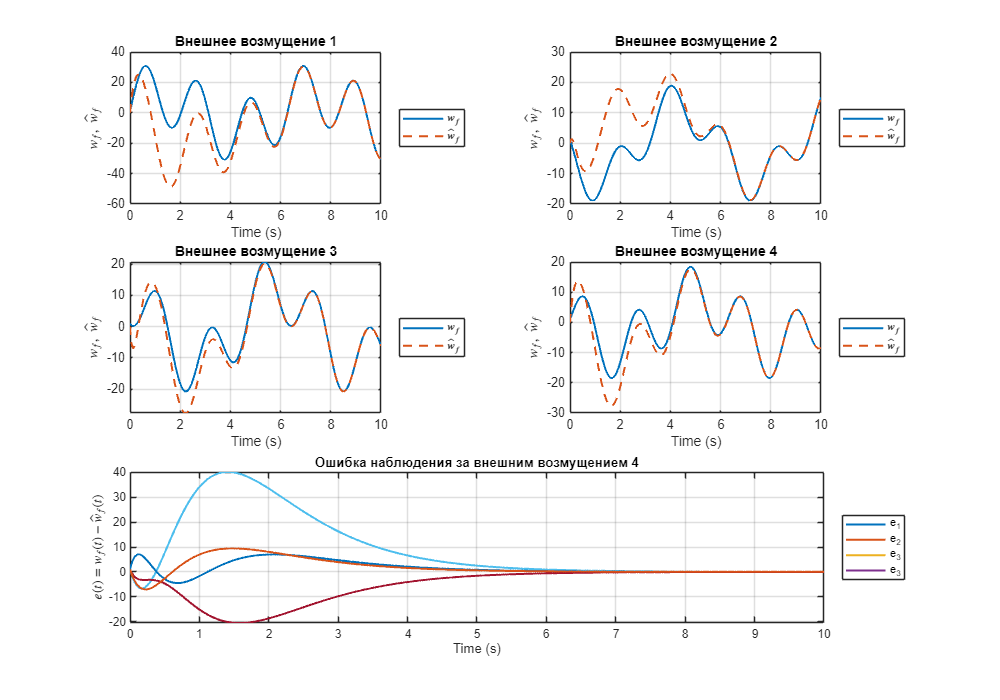

figure('Position', [0 0 1000 700]);
m = 3; % Number of rows
n = 2; % Number of columns

for i=1:4
    subplot(m, n, i);
    plot(out.wf.Time, out.wf.Data(:, i), 'LineWidth', 1.5); hold on;
    plot(out.wf_hat.Time, out.wf_hat.Data(:, i), '--', 'LineWidth', 1.5);
    title(['Внешнее возмущение ' int2str(i)]);
    legend({'$w_f$', '$\hat w_f$'}, 'Location', 'eastoutside', 'Interpreter', 'latex');
    xlabel('Time (s)');
    ylabel('$w_f,\ \hat w_f$', 'Interpreter', 'latex');
    grid on;
end

subplot(m, n, [5,6]);
for i=1:4
    plot(out.wf-out.wf_hat, 'LineWidth', 1.5); hold on;
end
title(['Ошибка наблюдения за внешним возмущением ' int2str(i)]);
legend({'e_1', 'e_2', 'e_3', 'e_3'}, 'Location', 'eastoutside');
xlabel('Time (s)');
ylabel('$e(t)=w_f(t)-\hat w_f(t)$', 'Interpreter', 'latex');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/33_sim.png'], 'Resolution', 500);